# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. Use `pyversion` before R2019b.

pyenv

       version: '3.6'
    executable: 'C:\Python36\WPy-3670\python-3.6.7.amd64\python.EXE'
       library: 'C:\Python36\WPy-3670\python-3.6.7.amd64\python36.dll'
          home: 'C:\Python36\WPy-3670\python-3.6.7.amd64'
      isloaded: 1


Test a simple function.

py.math.sqrt(42)

ans = 6.4807

Pass arguments using pyargs.

% py.textwrap.wrap("Hello world!",pyargs('width',2))   % errors

py.textwrap.wrap("Hello world!",pyargs('width',int8(2)))

ans =   Python list with no properties.

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

## Read weather data using Python module 

The weather.py module reads and parses current weather data from the web api: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Boston","US",apikey.Key(1))

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.06, 'lat': 42.36}, 'weather': [{'id': 802, 'main': 'Clouds', 'description': 'scattered clouds', 'icon': '03d'}], 'base': 'stations', 'main': {'temp': 82.31, 'pressure': 1005, 'humidity': 35, 'temp_min': 80.01, 'temp_max': 84.99}, 'visibility': 16093, 'wind': {'speed': 12.75, 'deg': 290}, 'clouds': {'all': 40}, 'dt': 1565374318, 'sys': {'type': 1, 'id': 3486, 'message': 0.012, 'country': 'US', 'sunrise': 1565343890, 'sunset': 1565394888}, 'timezone': -14400, 'id': 4930956, 'name': 'Boston', 'cod': 200}

Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 82.31, 'pressure': 1005, 'humidity': 35, 'temp_min': 80.01, 'temp_max': 84.99, 'speed': 12.75, 'deg': 290, 'city': 'Boston', 'lat': 42.36, 'lon': -71.06, 'current_time': '2019-08-09 14:23:53.228572'}

## Preprocess data 

The Python dictionary can be represented as a MATLAB struct.

data = struct(weatherData)

data = struct with fields:
            temp: 82.3100
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
        temp_min: 80.0100
        temp_max: 84.9900
           speed: 12.7500
             deg: [1×1 py.int]
            city: [1×6 py.str]
             lat: 42.3600
             lon: -71.0600
    current_time: [1×26 py.str]

Convert data to the desired MATLAB data types using the function below. 

convertData(data)

ans = 1×9 table
      T       P      RH    WindSpd    WindDir      city       lat      lon           DateLocal      
    _____    ____    __    _______    _______    ________    _____    ______    ____________________
    82.31    1005    35     12.75       290      "Boston"    42.36    -71.06    09-Aug-2019 14:23:53

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

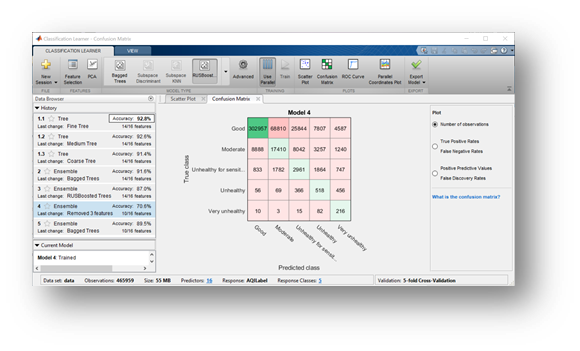

Use a function (`prepData.m`) to prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName        T       P       DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    _____    ____    _____    __    _______    _______    ____    __    __
    09-Aug-2019 14:23:53    "Boston"    Massachusetts    82.31    1005    58.91    35      290       12.75     2019    8     9 

Use the model to predict the air quality for the new weather data.

load airQualModel 

airQual = predict(model,currentData)

airQual = categorical
     Very unhealthy 

## Share prediction code

Create a function with these steps to be called in the Python environment.

edit predictAirQual.m

This function can now be tested in Python. See `CallMATLABfromPython.ipynb`

**Helper Function**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end